load ('Samsung_30Q_18650_pack.mat');
load ('VoltaicSystems_P110.mat');

addpath(genpath("Functions"));
addpath("Simulink/");

% Switching frequency:
boost.f = 1 * 10^5; % [Hz]
boost.T = 1/boost.f;

% Measurement filter cut-off:
boost.mfc = 2000; %[Hz]
boost.Tmfc = 1/(2*pi*boost.mfc);

% Maximum duty cycle that can be achieved:
boost.D_max = 1 - pv_data.Umpp/Bat.Ubat_nom; % MPP mode of operation

% Passive elements:
boost.Rt = 1*10^5;
boost.RL = 10 * 10^-3;
boost.Ru = 1;
boost.L = 50 * 10^-6;
boost.Cu = 1500 * 10^-6;
boost.Ci = 1200 * 10^-6;
boost.Cbat = Bat.Qbat_tot/(Bat.Ubat_charged - Bat.Ubat_cut_off);

## PV resistance:

% CCM:
pv_in.G = 800;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv_ccm = calc_pv_res("Solar_v2", pv_in);

% DCM
pv_in.G = 200;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv_dcm = calc_pv_res("Solar_v2", pv_in);

clear pv_in;

## Pick operating point:

% Pick operating point for simulation:

% CCM:
Upv_op = pv_ccm.Umpp;
idx = find(pv_ccm.Upv >= Upv_op, 1);
Ipv_op = pv_ccm.Ipv(idx);

ccm_in.Upv_op = Upv_op;
ccm_in.Ipv_op = Ipv_op;

%DCM
Upv_op = pv_dcm.Umpp;
idx = find(pv_dcm.Upv >= Upv_op, 1);
Ipv_op = pv_dcm.Ipv(idx);

dcm_in.Upv_op = Upv_op;
dcm_in.Ipv_op = Ipv_op;

clear idx;
clear Upv_op Ipv_op;

## Step input Settings:

% Step input settings:
stepp.step_time = 20 * 10^-3; % [ms]
% stepp.sim_time = 50 * 10^-3; % [ms]
stepp.sim_time = 0.2;

% Ir, Refrence current:
stepp.ir01 = ccm_in.Ipv_op + 0.05;
stepp.ir02 = dcm_in.Ipv_op; + 0.05;

[~, idx1] = min(abs(pv_ccm.Ipv - stepp.ir01));
[~, idx2] = min(abs(pv_dcm.Ipv - stepp.ir02));

stepp.upv1 = pv_ccm.Upv(idx1);
stepp.upv2 = pv_dcm.Upv(idx2);

% CCM:
stepp.d1 = ccm_op_CV(boost, Bat, pv_ccm).D0;
stepp.d2 = dcm_op_CV(boost, Bat, pv_dcm).D0;

clear idx1 idx2;

## Steady state operating point parameters:

ccm_op_mpp = ccm_op_MPP(boost, Bat, pv_ccm);
Upv0 = ccm_op_mpp.Upv0

Upv0 = 5.4891

Ipv0 = ccm_op_mpp.Ipv0

Ipv0 = 0.3587

Ubat0 = ccm_op_mpp.Ubat0

Ubat0 = 10.8000

Im0 = ccm_op_mpp.Im0

Im0 = -0.2992

m0 = ccm_op_mpp.m0

m0 = 2.4001e+04

ro = ccm_op_mpp.ro

ro = 0.4618

L_lim = ccm_op_mpp.L_lim

L_lim = 7.2971e-05

D0 = ccm_op_mpp.D0

D0 = 0.4917

Ir_lim = ccm_op_mpp.Ir_lim

Ir_lim = 0.6579


dcm_op_mpp = dcm_op_MPP(boost, Bat, pv_dcm);
Upv0 = dcm_op_mpp.Upv0

Upv0 = 5.4891

Ipv0 = dcm_op_mpp.Ipv0

Ipv0 = 0.3587

Ubat0 = dcm_op_mpp.Ubat0

Ubat0 = 10.8000

m0 = dcm_op_mpp.m0

m0 = 2.4001e+04

ro = dcm_op_mpp.ro

ro = 0.4474

D0 = dcm_op_mpp.D0

D0 = 0.2681


sim_op = ccm_op_mpp;

clear Upv0 Ipv0 Ubat0 Im0 m0 ro L_lim D0 Ir_lim;

## Plant model:

% CCM-MPP:
[Gp_ccm_mpp, ccm_sys_const_mpp] = ccm_sys_MPP(ccm_op_mpp, boost);

Gp_ccm_mpp

Gp_ccm_mpp =
 
     -7.067
  -------------
  0.02295 s + 1
 
Continuous-time transfer function.
Model Properties



1/ccm_sys_const_mpp.Tn

ans = 43.5651


% DCM-MPP:
[Gp_dcm_mpp, dcm_sys_const_mpp] = dcm_sys_MPP(dcm_op_mpp, boost);

Gp_dcm_mpp

Gp_dcm_mpp =
 
     -6.847
  -------------
  0.02295 s + 1
 
Continuous-time transfer function.
Model Properties


## Regulator:

% Ulazni parametri:
Gp = Gp_ccm_mpp;
param = ccm_sys_const_mpp;
sim_op = ccm_op_mpp;
%%%%%%%%%%%%%%%%%%%%%%%

Ti = param.Tn

Ti = 0.0230

KR = 1/param.K

KR = -0.1415


Ti = 0.0918;
KR = -3.082;

% Ti = PI.Kp/PI.Ki
% KR = PI.Kp

GR = tf([KR, KR/Ti], [1, 0]); 

G_full = GR * Gp;

## Bode:

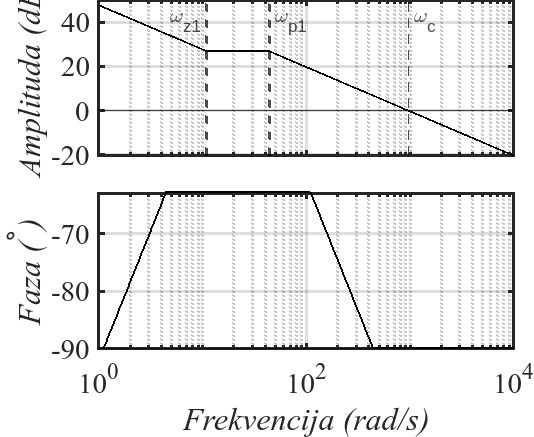


w = logspace(0, 4, 1000);
draw_bode(G_full, w);